# E10.13

## vi.

We will use the LMS algorithm to train the weights of this ADALINE network. The implementation is adopted from E10_4.mlx.

First we will use a stable learning rate, $\alpha =0\ldotp 3<1\ldotp 11$

We cannot use the same convergence condition as before because the squared error value fluctuates and the algorithm may terminate before it has actually converged.

We will use the following in the upcoming implementation of the LMS algorithm:


$$\begin{array}{l}
y\left(k\right)=\sin \left(\frac{\;k\pi }{5\;}\right)\\
t\left(k\right)=y\left(k\right)\\
p\left(k\right)=\left\lbrack \begin{array}{c}
y\left(k-1\right)\\
y\left(k-2\right)
\end{array}\right\rbrack 
\end{array}$$


% LMS Implementation
% initial guess
x_star = [0; 0];
x_hist = zeros([2, 41]);
x_hist(:, 1) = x_star;
error_hist = zeros([1, 40]);
num_steps = 40;
alpha = 0.3;
for iteration=1:num_steps
    iteration
    k = iteration - 1;
    % calculate y(k), y(k-1) and y(k-2) to construct the target value and
    % the input vectors.
    y_k = sin(k*pi/5);
    y_k_1 = sin((k-1)*pi/5);
    y_k_2 = sin((k-2)*pi/5);
    % target and inputs
    target = y_k;
    input = [y_k_1; y_k_2];
    error = target - x_star'*input
    error_hist(iteration) = error^2;
    x_star = x_star + 2*alpha*error*input
    x_hist(:, iteration+1) = x_star;
end

iteration = 1

error = 0

x_star =      0
     0


iteration = 2

error = 0.5878

x_star =          0
   -0.2073


iteration = 3

error = 0.9511

x_star =     0.3354
   -0.2073


iteration = 4

error = 0.7539

x_star =     0.7656
    0.0586


iteration = 5

error = -0.1961

x_star =     0.6537
   -0.0533


iteration = 6

error = -0.3336

x_star =     0.5361
   -0.2436


iteration = 7

error = -0.4446

x_star =     0.5361
   -0.4004


iteration = 8

error = -0.6360

x_star =     0.7604
   -0.4004


iteration = 9

error = -0.4633

x_star =     1.0247
   -0.2370


iteration = 10

error = 0.1613

x_star =     0.9327
   -0.3291


iteration = 11

error = 0.2352

x_star =     0.8497
   -0.4633


iteration = 12

error = 0.3154

x_star =     0.8497
   -0.5746


iteration = 13

error = 0.4516

x_star =     1.0090
   -0.5746


iteration = 14

error = 0.3292

x_star =     1.1968
   -0.4585


iteration = 15

error = -0.1144

x_star =     1.1315
   -0.5238


iteration = 16

error = -0.1670

x_star =     1.0727
   -0.6190


iteration = 17

error = -0.2239

x_star =     1.0727
   -0.6980


iteration = 18

error = -0.3206

x_star =     1.1857
   -0.6980


iteration = 19

error = -0.2337

x_star =     1.3190
   -0.6156


iteration = 20

error = 0.0812

x_star =     1.2727
   -0.6620


iteration = 21

error = 0.1185

x_star =     1.2309
   -0.7296


iteration = 22

error = 0.1589

x_star =     1.2309
   -0.7856


iteration = 23

error = 0.2276

x_star =     1.3112
   -0.7856


iteration = 24

error = 0.1659

x_star =     1.4058
   -0.7271


iteration = 25

error = -0.0577

x_star =     1.3729
   -0.7600


iteration = 26

error = -0.0841

x_star =     1.3432
   -0.8080


iteration = 27

error = -0.1128

x_star =     1.3432
   -0.8478


iteration = 28

error = -0.1615

x_star =     1.4002
   -0.8478


iteration = 29

error = -0.1177

x_star =     1.4674
   -0.8063


iteration = 30

error = 0.0409

x_star =     1.4440
   -0.8297


iteration = 31

error = 0.0597

x_star =     1.4230
   -0.8637


iteration = 32

error = 0.0801

x_star =     1.4230
   -0.8920


iteration = 33

error = 0.1147

x_star =     1.4634
   -0.8920


iteration = 34

error = 0.0836

x_star =     1.5111
   -0.8625


iteration = 35

error = -0.0291

x_star =     1.4945
   -0.8791


iteration = 36

error = -0.0424

x_star =     1.4796
   -0.9033


iteration = 37

error = -0.0568

x_star =     1.4796
   -0.9233


iteration = 38

error = -0.0814

x_star =     1.5083
   -0.9233


iteration = 39

error = -0.0593

x_star =     1.5421
   -0.9024


iteration = 40

error = 0.0206

x_star =     1.5304
   -0.9142


fprintf('#####\n\n Final Weights: [%f, %f]. Expected Weights: [%f, %f]', x_star(1), x_star(2), 14/9, -17/18)

#####

 Final Weights: [1.530358, -0.914176]. Expected Weights: [1.555556, -0.944444]

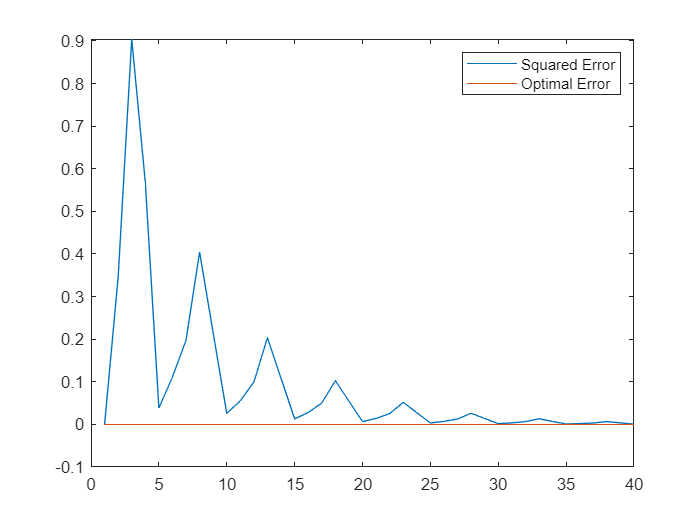

% plotting error history
plot(error_hist)
hold on
plot(zeros([1, 40]))
ylim([-0.1 max(error_hist)])
legend('Squared Error', 'Optimal Error')
hold off

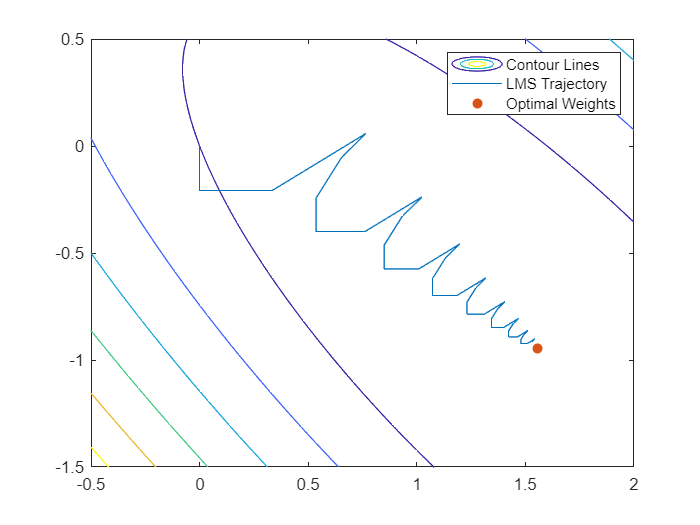

% sketching the trajectory on the contour plot
syms x1 x2 real
X = [x1; x2];
fx = 0.5 - 2*X'*[0.4; 0.15] + X'*[0.5 0.4; 0.4 0.5]*X;
fcontour(fx,[-0.5 2 -1.5 0.5])
hold on
plot(x_hist(1,:), x_hist(2,:));
hold on
scatter(14/9, -17/18, 'filled');
legend('Contour Lines', 'LMS Trajectory', 'Optimal Weights')
hold off

As we can see from the trajectory, the algorithm is slowly closing in on the optimal weights.

## vii.

Here we will run the same exact experiment except we will set the learning rate to an intentionally unstable value like $1\ldotp 12$ which is only slightly greater than the max stable learning rate.

% LMS Implementation
% initial guess
x_star = [0; 0];
x_hist = zeros([2, 41]);
x_hist(:, 1) = x_star;
error_hist = zeros([1, 40]);
num_steps = 40;
alpha = 1.12;
for iteration=1:num_steps
    iteration
    k = iteration - 1;
    % calculate y(k), y(k-1) and y(k-2) to construct the target value and
    % the input vectors.
    y_k = sin(k*pi/5);
    y_k_1 = sin((k-1)*pi/5);
    y_k_2 = sin((k-2)*pi/5);
    % target and inputs
    target = y_k;
    input = [y_k_1; y_k_2];
    error = target - x_star'*input
    error_hist(iteration) = error^2;
    x_star = x_star + 2*alpha*error*input
    x_hist(:, iteration+1) = x_star;
end

iteration = 1

error = 0

x_star =      0
     0


iteration = 2

error = 0.5878

x_star =          0
   -0.7739


iteration = 3

error = 0.9511

x_star =     1.2522
   -0.7739


iteration = 4

error = 0.2150

x_star =     1.7103
   -0.4908


iteration = 5

error = -0.5720

x_star =     0.4916
   -1.7094


iteration = 6

error = 1.3368

x_star =     2.2517
    1.1384


iteration = 7

error = -1.2569

x_star =     2.2517
   -0.5165


iteration = 8

error = 0.3725

x_star =     1.7613
   -0.5165


iteration = 9

error = 0.4205

x_star =     0.8656
   -1.0701


iteration = 10

error = -0.7823

x_star =     2.5321
    0.5965


iteration = 11

error = 2.0556

x_star = 2×1
   -0.1744
   -3.7828


iteration = 12

error = -1.6357

x_star = 2×1
   -0.1744
   -1.6292


iteration = 13

error = 1.0536

x_star = 2×1
    1.2128
   -1.6292


iteration = 14

error = 0.7552

x_star = 2×1
    2.8217
   -0.6348


iteration = 15

error = -1.4921

x_star = 2×1
   -0.3570
   -3.8136


iteration = 16

error = 3.8368

x_star = 2×1
    4.6946
    4.3602


iteration = 17

error = -3.1506

x_star = 2×1
    4.6946
    0.2119


iteration = 18

error = 1.8084

x_star = 2×1
    2.3136
    0.2119


iteration = 19

error = 1.3739

x_star = 2×1
   -0.6133
   -1.5970


iteration = 20

error = -2.6899

x_star = 2×1
    5.1172
    4.1335


iteration = 21

error = 6.9390

x_star = 2×1
   -4.0190
  -10.6492


iteration = 22

error = -5.6716

x_star = 2×1
   -4.0190
   -3.1817


iteration = 23

error = 3.3133

x_star = 2×1
    0.3435
   -3.1817


iteration = 24

error = 2.4945

x_star = 2×1
    5.6577
    0.1027


iteration = 25

error = -4.8907

x_star = 2×1
   -4.7612
  -10.3162


iteration = 26

error = 12.6099

x_star = 2×1
   11.8415
   16.5474


iteration = 27

error = -10.3141

x_star = 2×1
   11.8415
    2.9675


iteration = 28

error = 6.0092

x_star = 2×1
    3.9295
    2.9675


iteration = 29

error = 4.5304

x_star = 2×1
   -5.7218
   -2.9974


iteration = 30

error = -8.8803

x_star = 2×1
   13.1965
   15.9209


iteration = 31

error = 22.8983

x_star = 2×1
  -16.9524
  -32.8610


iteration = 32

error = -18.7274

x_star = 2×1
  -16.9524
   -8.2037


iteration = 33

error = 10.9154

x_star = 2×1
   -2.5807
   -8.2037


iteration = 34

error = 8.2275

x_star = 2×1
   14.9469
    2.6289


iteration = 35

error = -16.1278

x_star = 2×1
  -19.4112
  -31.7292


iteration = 36

error = 41.5859

x_star = 2×1
   35.3424
   56.8640


iteration = 37

error = -34.0116

x_star = 2×1
   35.3424
   12.0830


iteration = 38

error = 19.8227

x_star = 2×1
    9.2431
   12.0830


iteration = 39

error = 14.9418

x_star = 2×1
  -22.5885
   -7.5900


iteration = 40

error = -29.2892

x_star = 2×1
   39.8083
   54.8068


fprintf('#####\n\n Final Weights: [%f, %f]. Expected Weights: [%f, %f]', x_star(1), x_star(2), 14/9, -17/18)

#####

 Final Weights: [39.808335, 54.806827]. Expected Weights: [1.555556, -0.944444]

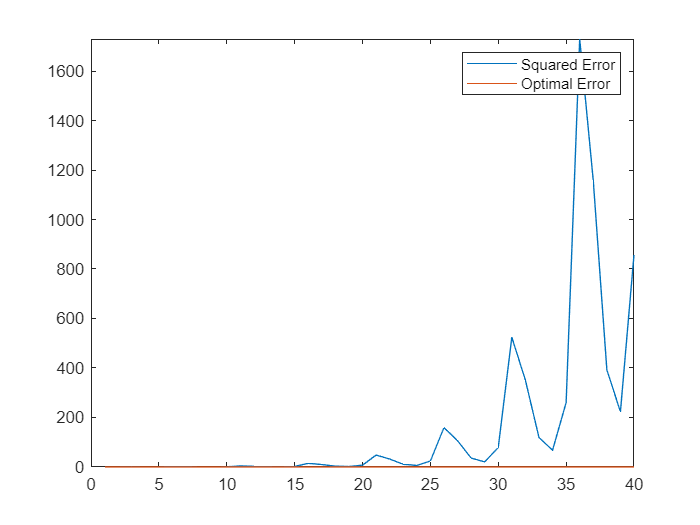

% plotting error history
plot(error_hist)
hold on
plot(zeros([1, 40]))
ylim([-0.1 max(error_hist)])
legend('Squared Error', 'Optimal Error')
hold off

As we can see the error is getting greater the further we go.

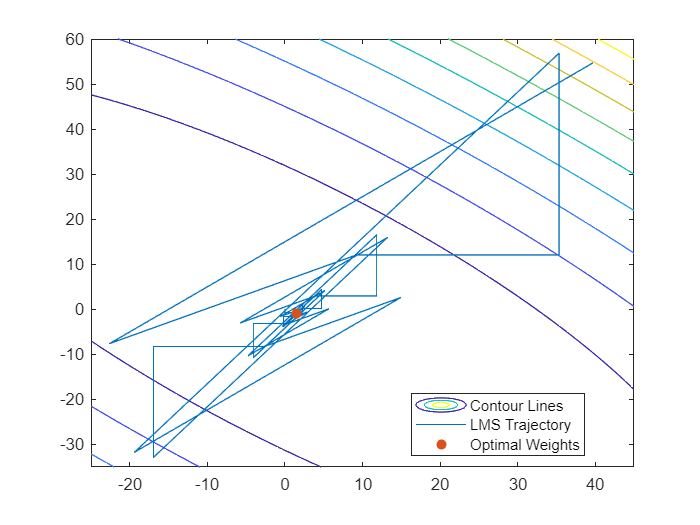

% sketching the trajectory on the contour plot
syms x1 x2 real
X = [x1; x2];
fx = 0.5 - 2*X'*[0.4; 0.15] + X'*[0.5 0.4; 0.4 0.5]*X;
fcontour(fx,[-25 45 -35 60])
hold on
plot(x_hist(1,:), x_hist(2,:));
hold on
scatter(14/9, -17/18, 'filled');
legend('Contour Lines', 'LMS Trajectory', 'Optimal Weights', 'location', 'best')
hold off

It is also obvious from the trajectory that the algorithm fails to converge, resulting in a messy trajectory that does not seem to be headed in any specific direction.